## **Probabilistic roadmap method con Breadth-first search (BFS)**

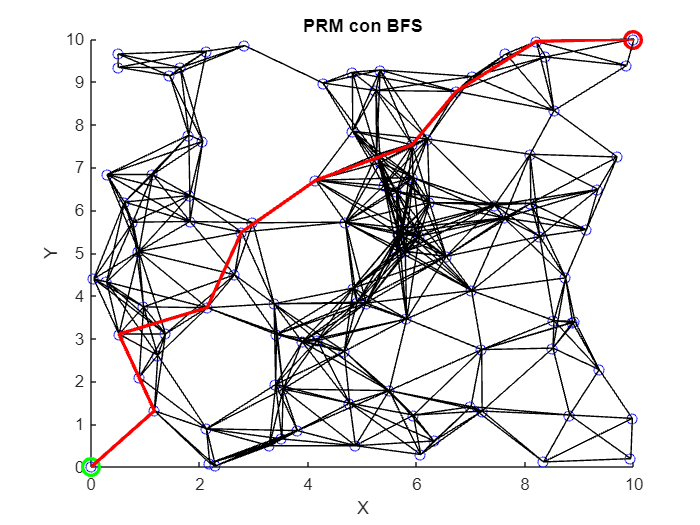

clear all; clc; close all;

% Parametri iniziali
numNodes = 100; % Numero di nodi nel roadmap
startPos = [0, 0]; % Punto iniziale Qs
goalPos = [10, 10]; % Punto finale Qg
xLimits = [0, 10];
yLimits = [0, 10];

% Genera nodi casuali
nodes = [startPos; goalPos];
while size(nodes, 1) < numNodes + 2
    newNode = [rand * (xLimits(2) - xLimits(1)) + xLimits(1), rand * (yLimits(2) - yLimits(1)) + yLimits(1)];
    nodes = [nodes; newNode];
end

% Costruzione del grafo
edges = [];
maxDist = 2; % Distanza massima per connettere i nodi
for i = 1:numNodes+2
    for j = i+1:numNodes+2
        if norm(nodes(i,:) - nodes(j,:)) < maxDist
            edges = [edges; i, j]; %#ok<AGROW>
        end
    end
end

% BFS per trovare il percorso dal nodo iniziale al nodo finale
graph = graph(edges(:,1), edges(:,2));
path = shortestpath(graph, 1, 2);

% Visualizza il roadmap e il percorso
figure;
hold on;
plot(nodes(:,1), nodes(:,2), 'bo');
plot(nodes(1,1), nodes(1,2), 'go', 'MarkerSize', 10, 'LineWidth', 2); % Punto iniziale
plot(nodes(2,1), nodes(2,2), 'ro', 'MarkerSize', 10, 'LineWidth', 2); % Punto finale
for i = 1:size(edges,1)
    plot([nodes(edges(i,1),1), nodes(edges(i,2),1)], [nodes(edges(i,1),2), nodes(edges(i,2),2)], 'k-');
end
plot(nodes(path,1), nodes(path,2), 'r-', 'LineWidth', 2); % Percorso trovato
title('PRM con BFS');
xlabel('X');
ylabel('Y');
hold off;